# mtRK Test

In this notebook, we're testing an implementation of tensor randomized Kaczmarz with masking and allowing multiple corruptions. Here we know locations of all corruptions.

Note: script requires the file mtRK.m (masking for multiple corruptions) 

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 20; % number of corruptions 
size_corrupt= 100; % size of corruptions 
num_its = 1000; % number of iterations

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);
B = tprod(A,X_true);

Now, let's test the implementation of tRK.

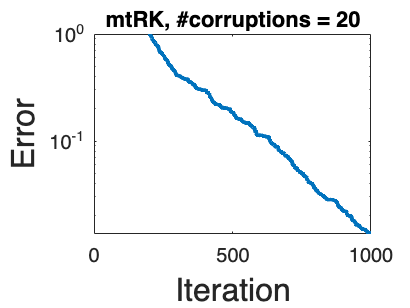

dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);

[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt; %original
end 

[~,its] = mtRK(A,B,randn(l,p,n),num_its, ix_sub1, ix_sub2);

%record errors
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];
end

%plot errors vs iterations
semilogy(errs,'Linewidth',2)
title("mtRK, #corruptions = " + num_corrupt)
xlabel ('Iteration', FontSize=16)
ylabel('Error', FontSize=16)
axis([0 num_its 0 1])